events=importSelectingData("StormEvents_2013.csv")

events = 59985×13 table
        State         Month         Event_Type          Begin_Date_Time      Timezone    Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  

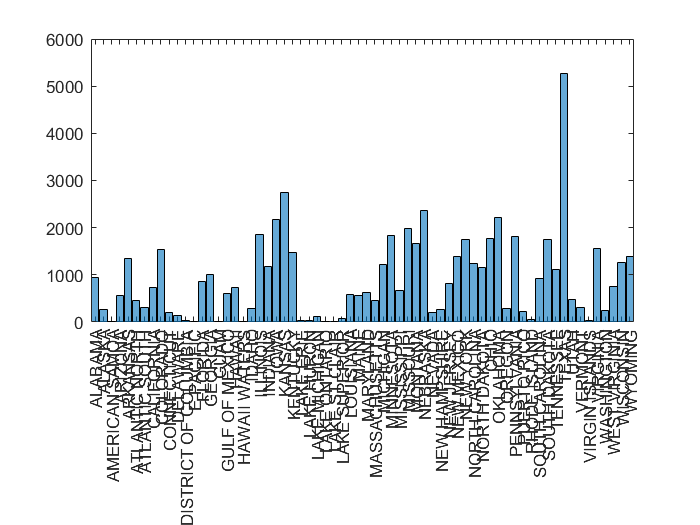

histogram(events.State)

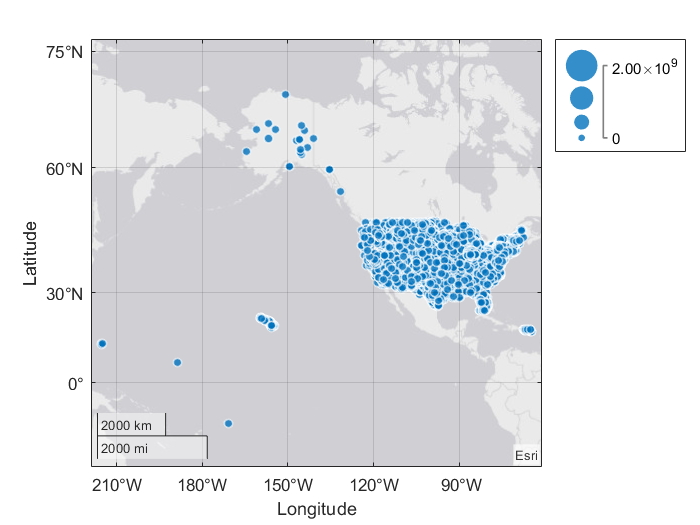

geobubble(events.Begin_Lat,events.Begin_Lon,events.Property_Cost);

events = movevars(events, 'Total_cost', 'Before', 'Begin_Lat');

Error using tabular/movevars (line 41)
Unrecognized table variable name 'Total_cost'.

writetable(events,"StormEvents_2013_withtotal.csv")

a=readtable

a = 406×9 table
         Mfg                        Model                    Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _____________    ____________________________________    __________    ___    ______    _________    __________    ____________    ____________

    {'chevrolet'}    {'chevrolet chevelle malibu'       }        70         18     3504         8           130              12            307     
    {'buick'    }    {'buick skylark 320'               }        70         15     3693         8           165            11.5            350     
    {'plymouth' }    {'plymouth satellite'              }        70         18     34

("Automobile Data.csv")

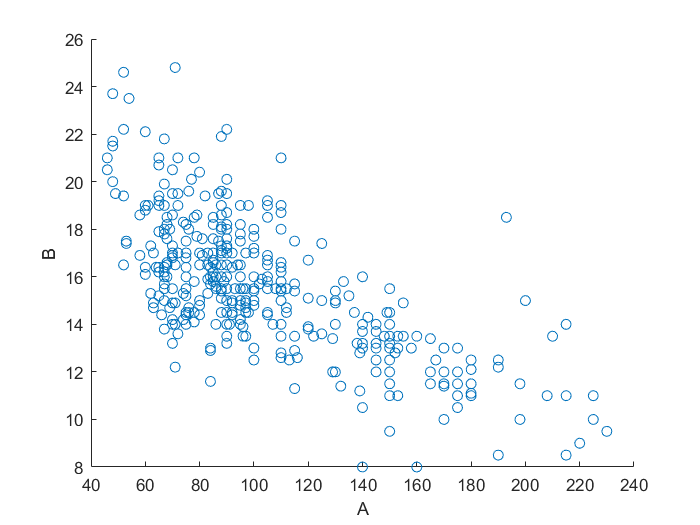

scatter(a.Horsepower,a.Acceleration)

xlabel('A')
ylabel('B')

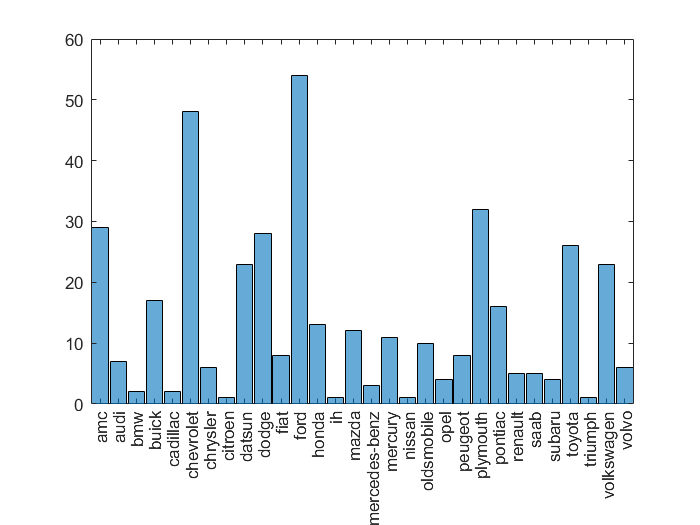

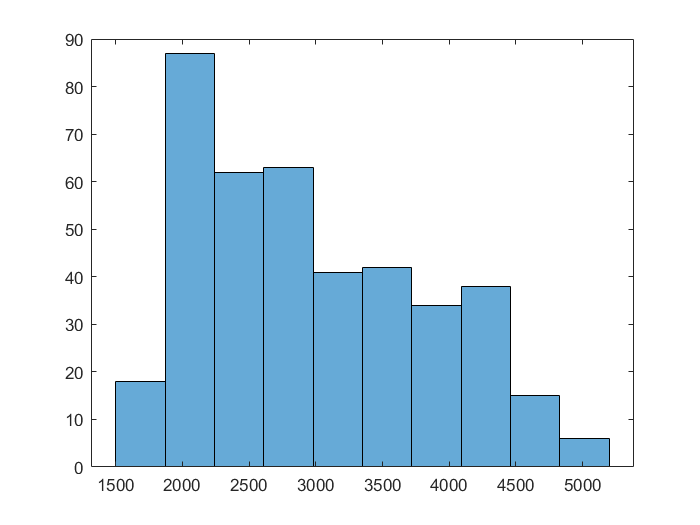


histogram(AutomobileData.Mfg)

AutomobileData

AutomobileData = AutomobileData(AutomobileData.Model_Year <= 79,:);
AutomobileData = AutomobileData(~ismissing(AutomobileData.MPG),:)

AutomobileData = 406×9 table
       Mfg                       Model                     Model_Year    MPG    Weight    Cylinders    Horsepower    Acceleration    Displacement
    _________    ______________________________________    __________    ___    ______    _________    __________    ____________    ____________

    chevrolet    "chevrolet chevelle concours (sw)    "        70        NaN     4142         8           165            11.5            350     
    ford         "ford torino (sw)                    "        70        NaN     4034         8           153              11            351     
    plymouth     "plymouth satellite (sw)             "        70        NaN    

histogram(AutomobileData.Weight,10)